## Part 2 **– **Analyzing the simulated data

Now that we have our simulated data in a format very similar to what we would expect in a real experiment, we can start analyzing this data. 

### Loading the data from part 1

clear all 
load('simulated_data1','spktimes','stim_type','stim_times','srate')

First we can extract the number spikes per some unit of time for each cell, and organize this data into different trials. We are going to use bins of 100 ms with no overlap, going from 1 s before the start of each stimulus and to 3 s after it. Our resultant structure is a N by T by B spike count matrix, where N is the number of neurons (20), T is the number of trials (100) and B is the number of bins (40, in this case).

binwidth = 0.1; % in seconds (100 ms)
bins = 0:binwidth*srate:4*srate;
bins=bins/srate;

n_cells=length(spktimes);
n_trials= length(stim_type);

spk_matrix = zeros(n_cells,n_trials,length(bins)-1);
for icell = 1:length(spktimes)
    
    spk = spktimes{icell};
    
    for itrial = 1:length(stim_times)
        idx = (spk>stim_times(itrial)-1 & spk<=stim_times(itrial)+3);
        
        spk_temp = spk(idx)-(stim_times(itrial)-1);
        
        count = histc(spk_temp,bins);
        
        % the last count is for values higher than the last bin edge, so we can discard it.
        count = count(1:end-1);
        
        spk_matrix(icell,itrial, :) = count;
        
    end
end

### Plotting an example neuron

Let's see the activity of one neuron across the time bins for different trials. Find a neuron in which you can clearly see the simulus modulation.

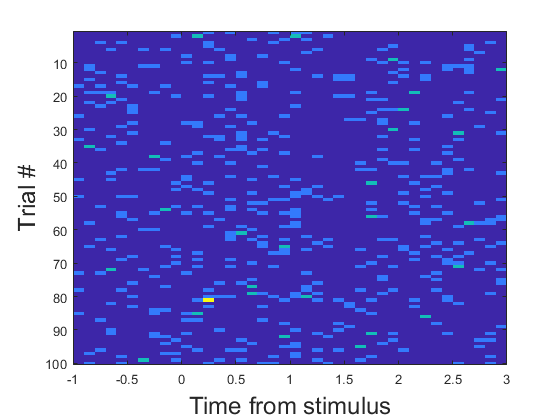


% let's define our time vector as the center of each bin
time_bins = bins(1:end-1)+binwidth/2;

% we also want the time 0 to be the moment of the stimulus
time_bins = time_bins -1;

clf
ineuron=12;
imagesc(time_bins,1:n_trials,squeeze(spk_matrix(ineuron,:,:)))
xlabel('Time from stimulus','FontSize',18)
ylabel('Trial #','FontSize',18)

## Creating a SVM classifier

With the activity of all the neurons separated in trials and time bins, we can now start training our SVM classifier. However, before going further, it is important to discuss two different sources of error in classification problems: the bias and the variance. 

Bias error arises from wrong assumptions made by the classifier, or limitations to extract the underlying relations between features of the data (e.g., underfitting). On the other hand, variance error arises from the variability of performance introduced by the sensitivity of the set of samples used to train the classifier (e.g., overfitting). 

We are going to see later a way of dealing with the bias. For now, we are going to use cross-validation to avoid overfitting. Cross validation consists in using different sets for training and testing, so that you don't risk creating a model that is overfitted to your sample. 

A simple way to do this is to use a K-fold crossvalidation scheeme. This consists in dividing your samples into K disjoints sets, and train K different models, separating, in each of them, a different set to test (and use the others sets to train). A common value for K is 10, but to simplify our computations we are going to use K=2.

% setting the 2-fold crossvalidation
k=2;
% creating 2 disjoints sets
C = cvpartition(n_trials,'KFold',k);
ibin=9;
performance=[];
for i=1:k
    % geting the training and test sets for the ith fold.
    trainingset = C.training(i);
    testset = C.test(i);
    
    % separating the activity of our bin of interest
    bin_matrix = squeeze(spk_matrix(:,:,ibin));
    % creating the SVM model with the training data
    SVMModel = fitcsvm(bin_matrix(:,trainingset)',stim_type(trainingset),'KernelFunction','linear','Standardize',false);
    
    % predicting the test data with the model
    [predicted_type,score] = predict(SVMModel,bin_matrix(:,testset)');
                                
    performance(i) = mean(predicted_type==stim_type(testset)');
end


The performance is then computed as the mean performance over the K-folds.

mean_performance = mean(performance)

mean_performance = 0.3700

Side note: if you have any trouble with the functions used to compute the SVM (*fitcsvm* and *predict*) you can replace them by a Naive-Bayes classifier. This can be done using the folowing line:

[predicted_type] = classify(bin_matrix(:,testset)',bin_matrix(:,trainingset)',stim_type(trainingset),'diaglinear');

## Question 1

Calculate the mean performance for all the time bins and make a plot of mean performance vs time from the stimulus.

bin_performances = [];

for b=1:length(time_bins)
    %train for bin:
    k=2;
    C = cvpartition(n_trials,'KFold',k);
    ibin=b;
    performance=[];
    for i=1:k
    % geting the training and test sets for the ith fold.
        trainingset = C.training(i);
        testset = C.test(i);
        bin_matrix = squeeze(spk_matrix(:,:,ibin));
        SVMModel = fitcsvm(bin_matrix(:,trainingset)',stim_type(trainingset),'KernelFunction','linear','Standardize',false);
        
        [predicted_type,score] = predict(SVMModel,bin_matrix(:,testset)');
        performance(i) = mean(predicted_type==stim_type(testset)');
    end
    bin_performances(b) = mean(performance);
    
end



perf = mean(bin_performances)

perf = 0.6533

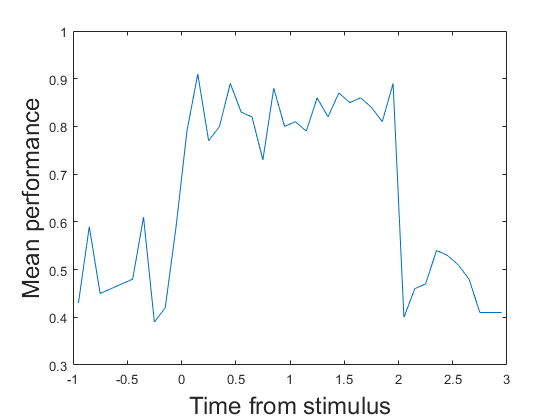

figure
plot(time_bins, bin_performances)
xlabel('Time from stimulus','FontSize',18)
ylabel('Mean performance','FontSize',18)

## Question 2

Explore different settings of the variable modulation (i.e., try to change the std of the distribution from which the its drawn). Compare the plot in Question 1 for each modulation value. What happens to the mean performance when you increase or decrease the std? 

Try to reason an explanation for the results you found. (Hint: try values like 0.1, 0.5

If the STD is increased, this means that the modulation can go further from the mean (1). This means that the modulation is more extreme.

That leads to a bigger difference in cell rate between the 2 stimuli. And a bigger difference between the firing rate for each of the stimuli makes it easier to distinguish them. Thus a higher performane is expected when the STD increases. The opposite holds if the STD decreases. 

The plot for STD = 0.1  is quite random, for the other plots the start of the stimulus is clearly visible. 

STD = 0.1 --> mean = 0.49

STD = 0.5 --> mean = 0.64 

STD = 0.9 --> mean = 0.68

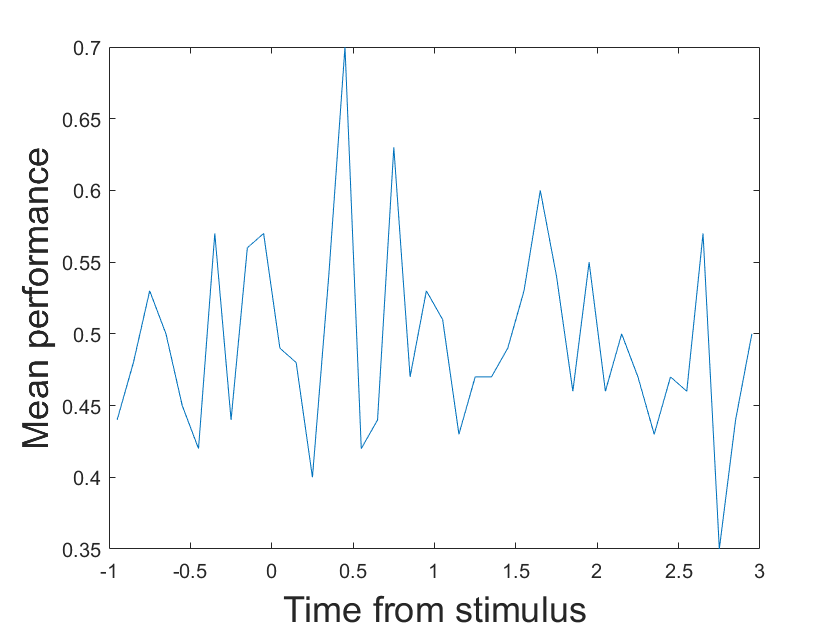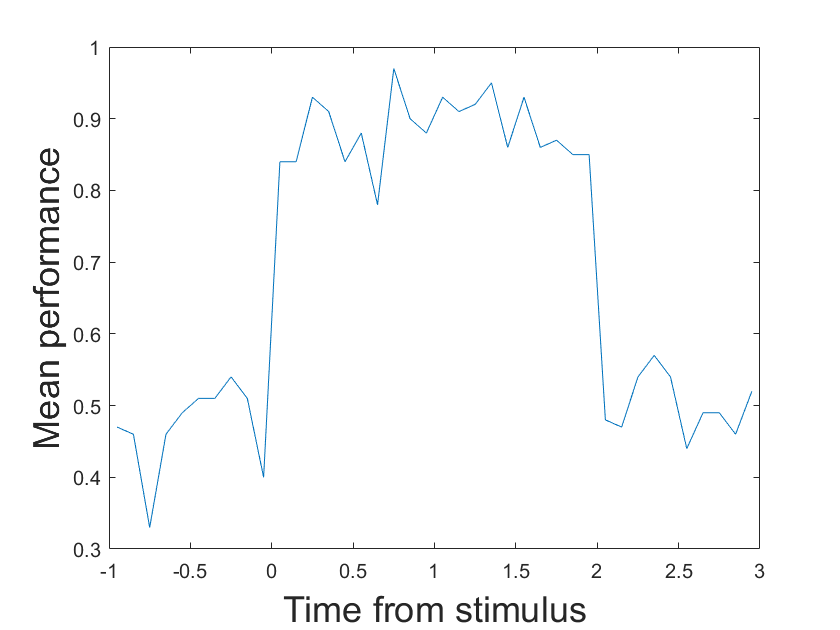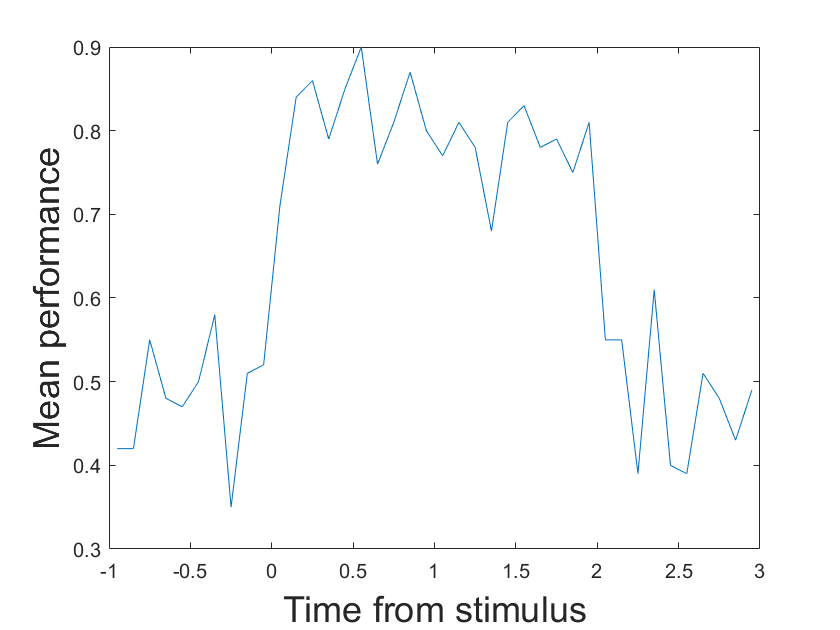

STD = 0.1                                                                        STD = 0.9                                                            STD = 0.5

## Assessing statistical significance with surrogates

Looking at the figure generated in question 1 we can see that, although there is no information about the stimulus in the first second of our trial, we can still see some fluctuations. How do we determine if each value is significantly above chance?

One way to do it is to try to 'destroy' any information about the stimulus type present in our data and see how high is this 'radom' performance. In fact, if we repeat this procedure multiple times, we can get a distribution of this 'radom' performance. This is called what we call a surrogate distribution. Let's implement it for two example timebins (bins 1 and 20).

We can start considering only one bin. In our case, bin 1. The following code computes the mean performance using a 2-fold crossvalidation.


k=2;
C = cvpartition(n_trials,'KFold',k);
ibin=1;
performance_bin1=[];
for i=1:k
    trainingset = C.training(i);
    testset = C.test(i);
    
    bin_matrix = squeeze(spk_matrix(:,:,ibin));
    SVMModel = fitcsvm(bin_matrix(:,trainingset)',stim_type(trainingset),'KernelFunction','linear','Standardize',false);
    
    [predicted_type,score] = predict(SVMModel,bin_matrix(:,testset)');
                                
    performance_bin1(i) = mean(predicted_type==stim_type(testset)');
end

mean_performance_bin1 = mean(performance_bin1);



Computing surrogates

n_surr = 100;
mean_surr_performance_bin1=zeros(1,n_surr);

for isurr=1:n_surr
    
    

For each surrogate let's randomly shuffle the stim_type.

    
    [v, rand_order] = sort(rand(1,length(stim_type))); % this is a trick to get shuffled indexes
    shuffled_stim_type = stim_type(rand_order); % and then we use those indexes on the stim_type vector
    

Now we just compute the mean performance for this surrogate using the shuffled labels (i.e., stim_type)

    performance_surr_bin1=[];
    for i=1:k
        trainingset = C.training(i);
        testset = C.test(i);
        
        bin_matrix = squeeze(spk_matrix(:,:,ibin));
        SVMModel = fitcsvm(bin_matrix(:,trainingset)',shuffled_stim_type(trainingset),'KernelFunction','linear','Standardize',false);
        
        [predicted_type,score] = predict(SVMModel,bin_matrix(:,testset)');
        
        performance_surr_bin1(i) = mean(predicted_type==stim_type(testset)');
    end
    
    mean_surr_performance_bin1(isurr) = mean(performance_surr_bin1);

end

Ploting the surrogate distribution and the real performance

clf
subplot(2,1,1)
bins = 0:0.01:1;
count = histc(mean_surr_performance_bin1,bins);
bar(bins,count)
hold on
plot(mean_performance_bin1*[1 1],ylim,'k--')
xlabel('Mean Performance')
ylabel('Counts')
title(['Bin ' num2str(ibin)])
legend({'Surrogate distribution', 'Real value'})


Now let's do the same for bin 20:

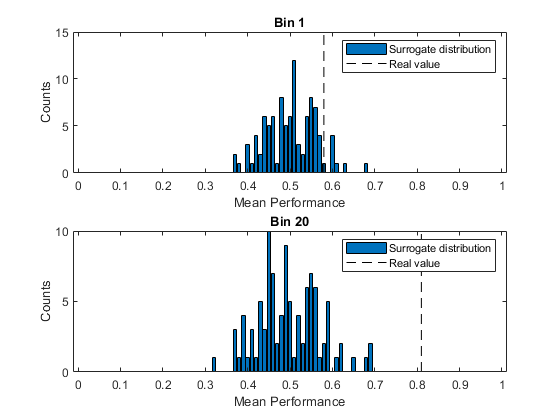


k=2;
C = cvpartition(n_trials,'KFold',k);
ibin=20;
performance_bin20=[];
for i=1:k
    trainingset = C.training(i);
    testset = C.test(i);
    
    bin_matrix = squeeze(spk_matrix(:,:,ibin));
    SVMModel = fitcsvm(bin_matrix(:,trainingset)',stim_type(trainingset),'KernelFunction','linear','Standardize',false);
    
    [predicted_type,score] = predict(SVMModel,bin_matrix(:,testset)');
                                
    performance_bin20(i) = mean(predicted_type==stim_type(testset)');
end

mean_performance_bin20 = mean(performance_bin20);


% Computing surrogates
n_surr = 100;
mean_surr_performance_bin20=zeros(1,n_surr);

for isurr=1:n_surr
    
    % for each surrogate let's randomly shuffle the stim_type.
    [v, rand_order] = sort(rand(1,length(stim_type))); % this is a trick to get shuffled indexes
    shuffled_stim_type = stim_type(rand_order); % and then we use those indexes on the stim_type vector
    
    % Now we just compute the mean performance for this surrogate using the
    % shuffled labels (i.e., stim_type)
    performance_surr_bin20=[];
    for i=1:k
        trainingset = C.training(i);
        testset = C.test(i);
        
        bin_matrix = squeeze(spk_matrix(:,:,ibin));
        SVMModel = fitcsvm(bin_matrix(:,trainingset)',shuffled_stim_type(trainingset),'KernelFunction','linear','Standardize',false);
        
        [predicted_type,score] = predict(SVMModel,bin_matrix(:,testset)');
        
        performance_surr_bin20(i) = mean(predicted_type==stim_type(testset)');
    end
    
    mean_surr_performance_bin20(isurr) = mean(performance_surr_bin20);

end


subplot(2,1,2)

bins = 0:0.01:1;
count = histc(mean_surr_performance_bin20,bins);
bar(bins,count)
hold on
plot(mean_performance_bin20*[1 1],ylim,'k--')
xlabel('Mean Performance')
ylabel('Counts')
title(['Bin ' num2str(ibin)])
legend({'Surrogate distribution', 'Real value'})

So now we have a surrogate distribution of performance along with the real performance for bin 1 and 20. Note that bin 1 has a real value really close to the mean of the surrogate distribution, while bin 20 has a far higher value than the rest of the distribution.

In fact, the mean of the surrogate distribution is an estimate of the bias of our classifier. Note that we can have different surrogate distributions for different timebins because they have different firing rate across the neurons. Now that we have surrogate distributions we can then think in a way of using it to normalize the real values, so that we can easily compare bins with diferent biases. For that, we are going to use the mean and the standard deviation (std) of the surrogates (Question 3).

### Interlude {

Since our shuffling procedures does not change the firing rate distribution of our training and test samples, we know that the diferences we find between the real value and the surrogate distribution are not due to a difference in firing rate. This is important because depending on what you want to test with your surrogate distribution you will have to think of the surrogates in a different way. 'Destroying' the source of information while keeping some other features of the original data such as firing rates or inter-spike interval it's not always trivial. (Remember this if you try to do the bonus question)

### }

## Question 3

Replot the graphs in the previous cells normalizing the distribution and the real performance $p$ by the mean $\mu$ and the std $\sigma$ of the surrogates using a Z-score transformation:


$$p_{\textrm{norm}} =\frac{\left(p-\mu \right)}{\sigma }$$


This means that the x-axis will measure how far the real value is from the mean in units of standard deviations. (Hint: the bins used to compute the histogram will be different after the transformation)

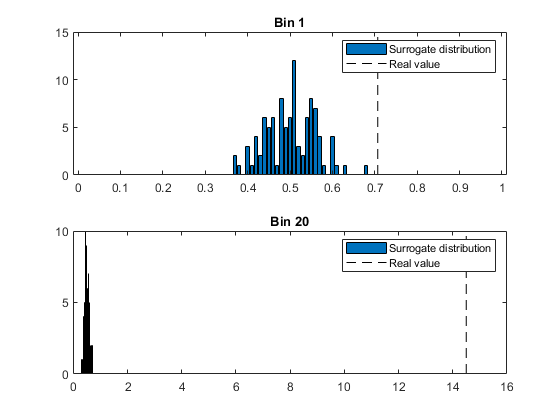

pnorm_bin1 = (performance_bin1 -performance_surr_bin1) ./ std(performance_surr_bin1);
pnorm_bin20 = (performance_bin20 - performance_surr_bin20) ./ std(performance_surr_bin20);
clf
subplot(2,1,1)
bins = 0:0.01:1;
count = histc(mean_surr_performance_bin1,bins);
bar(bins,count)
hold on
plot(mean(pnorm_bin1)*[1 1],ylim,'k--')
title(['Bin 1'])
legend({'Surrogate distribution', 'Real value'})
subplot(2,1,2)

bins = 0:0.01:1;
count = histc(mean_surr_performance_bin20,bins);
bar(bins,count)
hold on
plot(mean(pnorm_bin20)*[1 1],ylim,'k--')

title(['Bin 20'])
legend({'Surrogate distribution', 'Real value'})

## Question 4

Repeat the plot in Question 1 using the the z-scored values computed in the previous section. Also plot for each bin the maximum value of the (z-scored) surrogate distribution.

%computing surr for every bin:

means_surr = [];
stds_surr = [];
norm_performance = [];
for ibin=1:40
    % Computing surrogates
    n_surr = 100;
    mean_surr_performance_bin=zeros(1,n_surr);
    
    performances_for_every_surr = [];
    for isurr=1:n_surr
        
        % for each surrogate let's randomly shuffle the stim_type.
        [v, rand_order] = sort(rand(1,length(stim_type))); % this is a trick to get shuffled indexes
        shuffled_stim_type = stim_type(rand_order); % and then we use those indexes on the stim_type vector
        
        % Now we just compute the mean performance for this surrogate using the
        % shuffled labels (i.e., stim_type)
        performance_surr_bin=[];
        for i=1:k
            trainingset = C.training(i);
            testset = C.test(i);
            
            bin_matrix = squeeze(spk_matrix(:,:,ibin));
            SVMModel = fitcsvm(bin_matrix(:,trainingset)',shuffled_stim_type(trainingset),'KernelFunction','linear','Standardize',false);
            
            [predicted_type,score] = predict(SVMModel,bin_matrix(:,testset)');
            
        end
        performances_for_every_surr(isurr) = mean(predicted_type == stim_type(testset)');
    end
    max_values(ibin) = max(performances_for_every_surr);
    means_surr(ibin) = mean(performances_for_every_surr);
    stds_surr(ibin) = std(performances_for_every_surr);
   
end

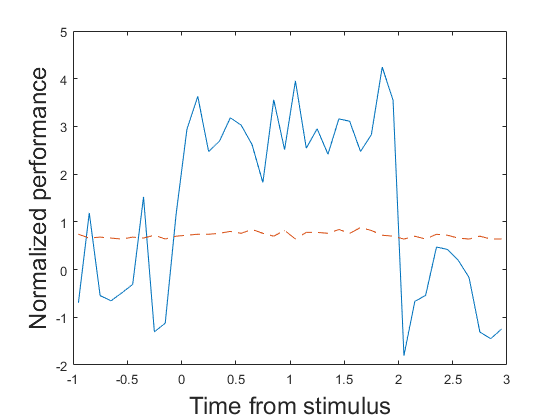

normalized_performance = (bin_performances - means_surr) ./ stds_surr;
max_values_normalized = (max_values - means_surr) ./stds_surr;
figure
plot(time_bins, normalized_performance)
hold on
plot(time_bins, max_values, '--')
xlabel('Time from stimulus','FontSize',18)
ylabel('Normalized performance','FontSize',18)

One important thing to notice here is that we can extract a significance value out of the surrogate distribution. In our case, because we only did 100 surrogates, the maximum surrogate value correspond to 1% of the distribution. So, if our real value is higher than this 1%, we can say that we have a *p-value* of p<0.01 (1%). In other words, if there is no information of the stimulus in the activity, and we repeat this experiment 100 times, we would have a spurious performance value higher than our real value in less than 1% of the times. That is what p<0.01 means.

Notice that if we increase the number of surrogates to 1000, for example, the threshold for p<0.01 would not be in the maximum value of the surrogate (that would be the 0.1%), but in the 10th higher value. 

Finally, we can also think in the reverse way. We can look into the rank of our real value in the surrogate distribution and extract an 'exact' *p-value.* For example, if our real value is the higher than the 97% of the surrogate distribution, we can say it has p=0.03.